import casadi.*
load('bajnok_hybrid_ai.mat'); 
agent = bajnok_agent; % Vagy amilyen néven elmentetted

disp('=== VÉGSŐ FÁZIS: Klasszikus vs. HIBRID AI (Zónás Szél Teszt) ===');

=== VÉGSŐ FÁZIS: Klasszikus vs. HIBRID AI (Zónás Szél Teszt) ===



% Ellenőrzés
if ~exist('net', 'var') || ~exist('net_sigma', 'var') || ~exist('agent', 'var')
    error('Hiba: Hiányzik valamelyik AI komponens (net, net_sigma, vagy agent)!');
end

% --- TÖBB KÖR EGYMÁS UTÁN FŰZÉSE ---
korok_szama = 1; 
egy_kor_pontjai = smooth_path(1:end-1, :); 
multi_lap_path = repmat(egy_kor_pontjai, korok_szama, 1);
multi_lap_path = [multi_lap_path; smooth_path(end, :)];

Ts = 0.1; V_target = 5; N = 15; 

ds = sqrt(diff(multi_lap_path(:,1)).^2 + diff(multi_lap_path(:,2)).^2);
dist = [0; cumsum(ds)];
t_path = dist / V_target; 
t_sim = 0:Ts:t_path(end); 

X_ref = interp1(t_path, multi_lap_path(:,1), t_sim, 'linear', 'extrap');
Y_ref = interp1(t_path, multi_lap_path(:,2), t_sim, 'linear', 'extrap');
RefMatrix = [X_ref', Y_ref', [diff(X_ref)/Ts, 0]', [diff(Y_ref)/Ts, 0]'];

A = [1 0 Ts 0; 0 1 0 Ts; 0 0 1 0; 0 0 0 1];
B = [0 0; 0 0; Ts 0; 0 Ts];
K_lqr = dlqr(A, B, diag([10, 10, 1, 1]), diag([0.5, 0.5]));

% ==========================================
% CASADI OPTIMIZÁCIÓS PROBLÉMA FELÉPÍTÉSE
% ==========================================
opti = casadi.Opti();

X = opti.variable(4, N+1); U = opti.variable(2, N);   
x0_param = opti.parameter(4, 1);         
ref_param = opti.parameter(4, N+1);      
w_nn_param = opti.parameter(4, 1); 
tube_scale_param = opti.parameter(1, 1); 

Q_mpc = diag([100, 100, 0, 0]); R_mpc = diag([0.1, 0.1]);     

cost = 0;
for k = 1:N
    err = X(:, k) - ref_param(:, k);
    cost = cost + err' * Q_mpc * err + U(:, k)' * R_mpc * U(:, k);
    opti.subject_to(X(:, k+1) == A * X(:, k) + B * U(:, k) + w_nn_param);
end
opti.minimize(cost + (X(:, N+1) - ref_param(:, N+1))' * Q_mpc * (X(:, N+1) - ref_param(:, N+1)));
opti.subject_to(X(:, 1) == x0_param);

% Dinamikus korlátok az RL ágens számára!
opti.subject_to( -(25 * tube_scale_param) <= U <= (25 * tube_scale_param) );

p_opts = struct('expand', true); 
s_opts = struct('max_iter', 100, 'print_level', 0, 'acceptable_tol', 1e-6); 
opti.solver('ipopt', p_opts, s_opts);

% ==========================================
% SZIMULÁCIÓS HUROK (Két futás egymás után)
% ==========================================
n_steps = length(t_sim) - N - 1;

% --- FAIR TESZT: Előre legenerált, közös alapzaj mindkét autónak ---
rng(42); % Fix seed
zaj_alap = randn(2, n_steps); % Nyers fehérzaj, amit zónánként skálázunk majd!

history_cl = zeros(n_steps, 4); errors_cl = zeros(n_steps, 1);
history_ai = zeros(n_steps, 4); errors_ai = zeros(n_steps, 1);
tube_history = zeros(n_steps, 1); 

for mode = 1:2
    if mode == 1
        disp('--> 1/2. Szimuláció: KLASSZIKUS MPC (Fix, konzervatív korlátokkal)...');
    else
        disp('--> 2/2. Szimuláció: HIBRID AI MPC (NN1 + NN2 + RL Karmester)...');
    end
    
    x_real = RefMatrix(1,:)'; z_nom = x_real; u_prev = [0; 0];
    
    for k = 1 : n_steps
        current_ref = RefMatrix(k : k+N, :)';
        
        if mode == 1
            % --- KLASSZIKUS MÓD ---
            w_becsult = [0; 0; 0; 0]; 
            current_scale = 0.8; 
        else
            % --- HIBRID AI MÓD ---
            % --- HIBRID AI MÓD ---
            nn_input = dlarray([x_real; u_prev], 'CB'); 
            
            % 1. Determinisztikus AI KIKAPCSOLÁSA (Nincs szélbecslés)
            % w_becsult = double(extractdata(predict(net, nn_input))); % Eredeti
            w_becsult = zeros(4, 1); % <--- FIX NULLA
            
            % 2. Sztochasztikus AI KIKAPCSOLÁSA (Nincs bizonytalanság-becslés)
            % w_sigma = double(extractdata(predict(net_sigma, nn_input))); % Eredeti
            w_sigma = zeros(4, 1); % <--- FIX NULLA
            
            % 3. RL Ágens KIKAPCSOLÁSA (Fix maximális mozgástér az MPC-nek)
            obs = [x_real(1)/100; (x_real(1:2)-z_nom(1:2))/5; x_real(3:4)/10; w_sigma(3:4)/1.5];
            obs = obs(:); 
            % action_cell = getAction(agent, {obs}); 
            % action_val = action_cell{1};
            current_scale = 1.0; % <--- FIX 1.0 (Maximum cső, maximális beavatkozás)
            
            tube_history(k) = current_scale;
        end
        
        opti.set_value(x0_param, z_nom);       
        opti.set_value(ref_param, current_ref);
        opti.set_value(w_nn_param, w_becsult); 
        opti.set_value(tube_scale_param, current_scale);
        
        try, sol = opti.solve(); v_k_opt = sol.value(U(:, 1)); 
        catch, v_k_opt = opti.debug.value(U(:, 1)); end
        
        u_k = v_k_opt - K_lqr * (x_real - z_nom);
        u_k = max(min(u_k, 25), -25);
        
        drag_x = -0.02 * x_real(3) * abs(x_real(3)) * Ts;
        drag_y = -0.02 * x_real(4) * abs(x_real(4)) * Ts;
        const_wind_x = 0.8 * Ts; const_wind_y = 0.5 * Ts;
        
        % --- HETEROSZKEDASZTIKUS ZAJ (Pozíciófüggő Vihar) ---
        if x_real(1) > 40
            zaj_x = zaj_alap(1, k) * 1.5; % Völgy (Vihar)
            zaj_y = zaj_alap(2, k) * 1.5;
        else
            zaj_x = zaj_alap(1, k) * 0.1; % Erdő (Nyugodt)
            zaj_y = zaj_alap(2, k) * 0.1;
        end

        w_x = const_wind_x + drag_x + zaj_x;
        w_y = const_wind_y + drag_y + zaj_y;
        w_k = [0; 0; w_x; w_y];
        
        x_real = A * x_real + B * u_k + w_k;
        z_nom = A * z_nom + B * v_k_opt + w_becsult; 
        u_prev = u_k;
        
        tavolsagok = sqrt((smooth_path(:,1) - x_real(1)).^2 + (smooth_path(:,2) - x_real(2)).^2);
        valodi_terbeli_hiba = min(tavolsagok);

        if mode == 1
            history_cl(k, :) = x_real'; errors_cl(k) = valodi_terbeli_hiba; 
        else
            history_ai(k, :) = x_real'; errors_ai(k) = valodi_terbeli_hiba; 
        end
    end
end

--> 1/2. Szimuláció: KLASSZIKUS MPC (Fix, konzervatív korlátokkal)...


      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  30.00us (  3.75us)         8
       nlp_g  |        0 (       0)  53.00us (  6.62us)         8
  nlp_grad_f  |        0 (       0)  29.00us (  3.22us)         9
  nlp_hess_l  |        0 (       0)  14.00us (  2.00us)         7
   nlp_jac_g  |        0 (       0)  29.00us (  3.22us)         9
       total  |  32.00ms ( 32.00ms)  32.21ms ( 32.21ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  21.00us (  2.62us)         8
       nlp_g  |        0 (       0)  45.00us (  5.62us)         8
  nlp_grad_f  |        0 (       0)  28.00us (  3.11us)         9
  nlp_hess_l  |        0 (       0)  15.00us (  2.14us)         7
   nlp_jac_g  |        0 (       0)  28.00us (  3.11us)         9
       total  |  16.00ms ( 16.00ms)  15.45ms ( 15.45ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp

--> 2/2. Szimuláció: HIBRID AI MPC (NN1 + NN2 + RL Karmester)...


      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  49.00us (  3.50us)        14
       nlp_g  |        0 (       0) 100.00us (  7.14us)        14
  nlp_grad_f  |        0 (       0)  52.00us (  3.47us)        15
  nlp_hess_l  |        0 (       0)  53.00us (  4.08us)        13
   nlp_jac_g  |        0 (       0)  66.00us (  4.40us)        15
       total  |  34.00ms ( 34.00ms)  34.82ms ( 34.82ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)  22.00us (  2.00us)        11
       nlp_g  |        0 (       0)  43.00us (  3.91us)        11
  nlp_grad_f  |   1.00ms ( 83.33us)  31.00us (  2.58us)        12
  nlp_hess_l  |        0 (       0)  19.00us (  1.90us)        10
   nlp_jac_g  |        0 (       0)  34.00us (  2.83us)        12
       total  |  19.00ms ( 19.00ms)  18.02ms ( 18.02ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp


% ==========================================
% GRAFIKUS KIÉRTÉKELÉS (Teljes Sötét Mód)
% ==========================================
disp('=== SZIMULÁCIÓK KÉSZ. Ábrázolás... ===');

=== SZIMULÁCIÓK KÉSZ. Ábrázolás... ===


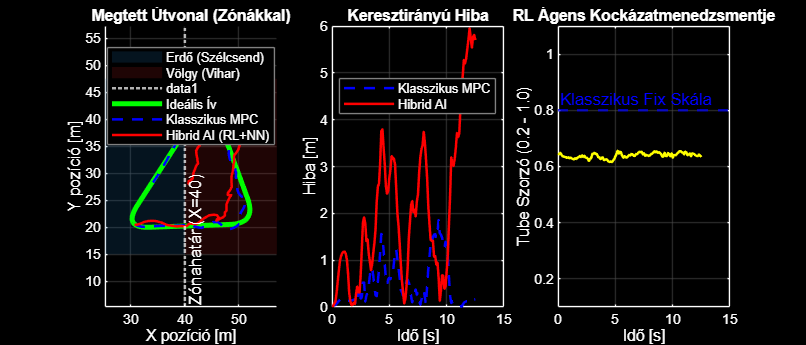


figure('Name', 'MPC Összehasonlítás: Zónás Szél Teszt', 'Position', [50, 50, 1400, 600], 'Color', 'k');

% --- 1. PANEL: Útvonalak és Szélzónák ---
ax1 = subplot(1, 3, 1);
hold on; grid on;

y_min = min(smooth_path(:,2)) - 5;
y_max = max(smooth_path(:,2)) + 5;
x_max = max(smooth_path(:,1)) + 5;
x_min = min(smooth_path(:,1)) - 5;

% 1. Szélvédett Zóna rajzolása (X <= 40) - Halványkék
patch([x_min, 40, 40, x_min], [y_min, y_min, y_max, y_max], [0.1 0.4 0.6], ...
      'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', 'Erdő (Szélcsend)');

% 2. Viharzóna rajzolása (X > 40) - Halványpiros
patch([40, x_max, x_max, 40], [y_min, y_min, y_max, y_max], [0.6 0.1 0.1], ...
      'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', 'Völgy (Vihar)');

xline(40, 'w:', 'Zónahatár (X=40)', 'LineWidth', 1.5, 'LabelVerticalAlignment', 'bottom');

plot(smooth_path(:,1), smooth_path(:,2), '-g', 'LineWidth', 3, 'DisplayName', 'Ideális Ív'); 
plot(history_cl(:,1), history_cl(:,2), 'b--', 'LineWidth', 1.5, 'DisplayName', 'Klasszikus MPC');
plot(history_ai(:,1), history_ai(:,2), 'r-', 'LineWidth', 1.5, 'DisplayName', 'Hibrid AI (RL+NN)');

lgd1 = legend('Location', 'best'); title('Megtett Útvonal (Zónákkal)', 'Color', 'w');
xlabel('X pozíció [m]', 'Color', 'w'); ylabel('Y pozíció [m]', 'Color', 'w'); axis equal;
set(ax1, 'Color', 'k', 'XColor', 'w', 'YColor', 'w', 'GridColor', [0.3 0.3 0.3], 'GridAlpha', 0.5); 
set(lgd1, 'TextColor', 'w', 'Color', 'k', 'EdgeColor', [0.5 0.5 0.5]);

% --- 2. PANEL: Követési hiba ---
ax2 = subplot(1, 3, 2);
plot(t_sim(1:n_steps), errors_cl, 'b--', 'LineWidth', 1.5, 'DisplayName', 'Klasszikus MPC'); hold on; grid on;
plot(t_sim(1:n_steps), errors_ai, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Hibrid AI');
lgd2 = legend('Location', 'best'); title('Keresztirányú Hiba', 'Color', 'w');
xlabel('Idő [s]', 'Color', 'w'); ylabel('Hiba [m]', 'Color', 'w');
set(ax2, 'Color', 'k', 'XColor', 'w', 'YColor', 'w', 'GridColor', [0.3 0.3 0.3], 'GridAlpha', 0.5); set(lgd2, 'TextColor', 'w', 'Color', 'k', 'EdgeColor', [0.5 0.5 0.5]);

% --- 3. PANEL: RL Ágens Döntései (Tube Skála) ---
ax3 = subplot(1, 3, 3);
plot(t_sim(1:n_steps), tube_history, 'y-', 'LineWidth', 1.5); hold on; grid on;
yline(0.8, 'b--', 'Klasszikus Fix Skála', 'Color', 'b', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left');
title('RL Ágens Kockázatmenedzsmentje', 'Color', 'w');
xlabel('Idő [s]', 'Color', 'w'); ylabel('Tube Szorzó (0.2 - 1.0)', 'Color', 'w');
ylim([0.1 1.1]);
set(ax3, 'Color', 'k', 'XColor', 'w', 'YColor', 'w', 'GridColor', [0.3 0.3 0.3], 'GridAlpha', 0.5);


% --- STATISZTIKA ---
mean_cl = mean(errors_cl);
mean_ai = mean(errors_ai);
javulas = (1 - (mean_ai / mean_cl)) * 100;

fprintf('\n=== VÉGSŐ HIBRID EREDMÉNYEK ===\n');


=== VÉGSŐ HIBRID EREDMÉNYEK ===


fprintf('Klasszikus MPC átlagos letérés a viharban:   %.4f m\n', mean_cl);

Klasszikus MPC átlagos letérés a viharban:   0.5047 m


fprintf('Hibrid AI (RL+NN) átlagos letérés:           %.4f m\n', mean_ai);

Hibrid AI (RL+NN) átlagos letérés:           2.0652 m


fprintf('----------------------------------------------\n');

----------------------------------------------


fprintf('JAVULÁS A VIHARBAN:                         +%.1f %%\n', javulas);

JAVULÁS A VIHARBAN:                         +-309.2 %



max_cl = max(errors_cl);
max_ai = max(errors_ai);
max_javulas = (1 - (max_ai / max_cl)) * 100;

fprintf('Klasszikus MPC maximális letérése:   %.4f m\n', max_cl);

Klasszikus MPC maximális letérése:   1.8591 m


fprintf('Hibrid AI maximális letérése:        %.4f m\n', max_ai);

Hibrid AI maximális letérése:        5.9502 m


fprintf('A LEGROSSZABB ESET (TÚLÉLÉS) JAVULÁSA: +%.1f %%\n', max_javulas);

A LEGROSSZABB ESET (TÚLÉLÉS) JAVULÁSA: +-220.1 %
